# Tutorial 8. Machine Learning

Athena Liu

Mar 24, 2020

While you are waiting, please download the scripts and dataset from Canvas/Modules/Tutorial 8 :)

Session starts at 10am!

**[Start Recording!]**

*Notice: You will need the "Statistics and Machine Learning Toolbox" in MATLAB to use some of the functions in this tutorial. If you run this script in your computer and see "function not found", it means you don't have that toolbox installed. Just search in MATLAB help to download it.*

## Background Scenario

In this tutorial, we will build machine learning models to help a car retail company to "learn" their customer behaviour. 

They have collected some data on their previous customers and listed in "*Car_Advertisement.csv*". In the datashee, you can see:

- User ID (instead of names, the company is using an ID to protect their privacy!)

- Gender 

- Age

- Salary

- The result: whether or not they purchased a car

Using these data, the company want to be build a ML model that can predict if a new customer will purchase a car based on their gender, age and salary.

## Machine Learning Project Procedures

We want to demonstrate to you the standard procedures to do a machine learning project using the car advertisement case.

We are going through the following steps:

- Frame the problem and look at the big picture.

- Get the data. Split into training and testing set, and set aside the testing set for now.

- Explore the data. Get some insight!

- Pre-processing the data to better expose the underlying data patterns to ML algorithms.

- Try out different ML models. In this tutorial we will try 5 models: **discriminant analysis model, KNN, Naive Bayes, SVM-linear, SVM-nonlinear.**

- Fine-tune your models. Once you are confident about your final model, measure its performance on the test set to estimate the generalization error.

- Present your solution. Lauch your model.

* This checklist is adapted from* Hands-On Machine Learning with Scikit-Learn, Keras, and TensorFlow *by Aurelien Geron. It is free to read online for all UBC students. I recommend it if you want to learn more about doing ML in Python!

# Step 1: Frame the problem

Using "Car_Advertisement.csv", we want to help the company to build a ML model that can predict if a new customer will purchase a car based on their gender, age and salary as accurately as possible.

# Step 2: Get the Data

This step invovles surveying the customers in an ethical manner. The company has already done that, so let's just load the dataset.

data = readtable('Car_Advertisement.csv');
data.Properties.VariableNames % Column names in the dataset

ans = 1×5 cell array
    {'UserID'}    {'Gender'}    {'Age'}    {'EstimatedSalary'}    {'Purchased'}


Note that 'Gender' and 'Purchased' should be categorical data, so let's convert them:

data.Gender = categorical(data.Gender);
data.Purchased = categorical(data.Purchased);

Also, keeping track of the number of samples:

m = height(data); % Number of entries in the dataset

## Train-Test Split

It is very important that you split the data into training and testing set now.

**Set aside the testing set and don't look at it until step 6!** 

This is because you don't want to overfit your data by accidentally identifying some patterns in the testing data and select your model to (over-)fit the testing data.

cv = cvpartition(height(data), 'HoldOut', 0.2); % Reserve 20% data as test set
train_data = data(cv.training,:); % Training data set
test_data = data(cv.test,:); % Testing data set - set aside for now!

# Step 3: Explore the Data

Let's study the `train_data:`

## Study each attribute and its characteristics

This is a supervised learning problem. There are 5 attributes in the dataset, among them, there are 

- 4 **Features** {'UserID'  'Gender'  'Age'  'EstimatedSalary'} -- the attributes that we use to make predictions with, denoted by "X"

- 1 **Target** {'Purchased'} -- the attribute that we want to predict, denoted by "Y"

X = train_data(:, {'Gender', 'Age', 'EstimatedSalary'});
Y = train_data.Purchased;
m_train = height(X); % number of samples in the training set

It's a good idea of have some basic statistics on X:

summary(X)


Variables:

    Gender: 320×1 categorical

        Values:

            Female      163   
            Male        157   

    Age: 320×1 double

        Values:

            Min        18  
            Median     37  
            Max        60  

    EstimatedSalary: 320×1 double

        Values:

            Min              15000     
            Median           70000     
            Max            1.5e+05     



summary(Y)

     Not Purchased      202 
     Purchased          118 


## Visualize the data for numerical data

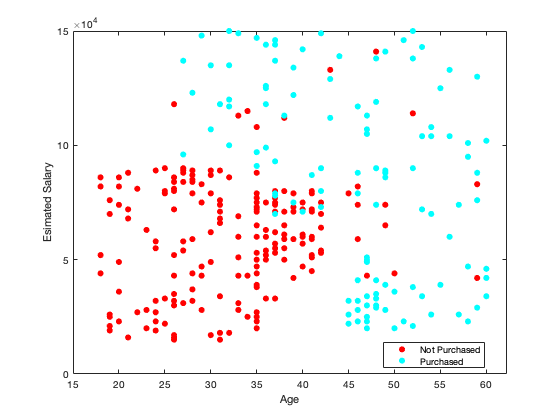

figure(10)
gscatter(X.Age, X.EstimatedSalary, Y)
xlabel('Age')
ylabel('Esimated Salary')

It looks like rich / older people tends to purchase cars than poor / younger people. 

'Age' and 'Salary' will be useful attributes to add to our ML models next.

## Correlations between Categorical Features and Y

Also, let's see if Gender plays a role in if people would buy a car or not.

We can do a Chi-square test on this! 

H0: Purchasing proportion among Male customers = Purchasing proportion among Female customers

% Observed data
n_mp = sum((X.Gender == "Male" ) .* (Y == "Purchased"));
N_m = sum(X.Gender == "Male" );
n_fp = sum((X.Gender == "Female" ) .* (Y == "Purchased"));
N_f = sum(X.Gender == "Female" );

% Pooled estimate of proportion
p0 = (n_mp+n_fp) / (N_m+N_f)

p0 = 0.3688

% Expected counts under H0 (null hypothesis)
n_mp0 = N_m * p0;
n_fp0 = N_f * p0;

% Chi-square test
observed = [n_mp N_m-n_mp n_fp N_f-n_fp];
expected = [n_mp0 N_m-n_mp0 n_fp0 N_f-n_fp0];
chi2stat = sum((observed-expected).^2 ./ expected)

chi2stat = 0.1927

p = 1 - chi2cdf(chi2stat,1)

p = 0.6607

p value is > signaficant level 0.05, we fail to reject the null hypothesis.

So it is very likely that Gender does not play a role in deciding whether a customer would buy a car. 

At this point, we can drop the `{Gender}` attribute from `X` , but let's keep it for now so that I can demonstrate a few more things to you about categorical features.

# Step 4: Pre-processng the Data

It is always a good idea to prepare the data a little bit to better expose the underlying data patterns to ML algorithms.

## Handling Categorical Features

Notice that "Gender" is categorical data, but usually** ML models only take numerical features**. 

So we need to convert it to numerical data by "*encoding*" the data.

Let's be feminist and set "Female" = 1 and "Male" = 0. (Unfortonately, this company did not collect data for non-binary people.)

X.Gender = double(X.Gender == 'Female');

## Feature Scaling: Standardization

Also notice that the current data have different means and standard deviations, which will cause many ML algorithms to perform badly.

To avoid this, we need to **"standardize" the data** by scaling the data with its mean and standard deviation. This way, the data at each feature will center around zero and have the same "spread". This step will improve the performance of the ML models greatly.


$$x_i := \frac{x_i - \mu_i}{\sigma_i}$$


X.Age = (X.Age - mean(X.Age))/std(X.Age);
X.EstimatedSalary = (X.EstimatedSalary - mean(X.EstimatedSalary))/std(X.EstimatedSalary);
X.Gender = (X.Gender - mean(X.Gender))/std(X.Gender);

The above code is equivalize to do just:

% X = normalize(X);

## Feature Selection: Drop Useless Features

We have found in our first step that `Gender` is likely useless in predcting `Purchased or not`.

Just to be sure, there is another way to test it out - by running a Logistic Regression.

**(Logistic Regression** is very similar to Multiple Linear Regression, only difference is that the output is a "Yes or No" instead of a number.)

[B,dev,stats] = mnrfit(X{:,:},Y);
B

B =     1.0539
    0.1488
   -2.3886
   -1.2223


The logistic regression results is saying


$$Purchased \sim 1.25 + 0.12*Gender -2.76*Age-1.588*Salary$$


The coefficient for `Gender` is much smaller than `Age` and `Salary`, so we proved again that `Gender` is not useful here.

Let's drop it:

X = X(:, {'Age', 'EstimatedSalary'});

In your assignment, you can explore the "usefulness" of the features using a logistic regression as well, and drop the useless features.

# Step 5: Try out Different ML Models

Finally!!! We are here to use ML models. 

( I know that you all want to dive into ML models immediately, but it is essesntial that you do the previous steps first to make sure that the ML models work properly. )

We will try 5 classification models:

## Model 1: Linear Discriminant Analysis Classifier

Train a discriminant analysis classifier using `fitcdiscr` :

da_clf = fitcdiscr(X, Y);

Now let's use the trained classifier to make predictions on the training set:

Y_pred = da_clf.predict(X);

How many of them are correctly predicted? Let's compare with actual answers.

Calculate the accuracy score = percentage of samples that are predicted correctly:

accuracy_score = sum((Y_pred == Y))/m_train

accuracy_score = 0.8406

85% accurate, that's pretty good! But don't be too excited -- the classifier might also be overfitting the data! The model may fit the training data very well but does not generalize well to the data that it has not seen. 

To examie how well a model generalize to new data, we will use a technique called **cross-validation**.

### k-fold Cross Validation

We will do a k-fold cross validation, by default k=10.

The code below divides the training dataset into 10 folds and trains the model 10 times on 9 folds each time, using the remaining fold as the test set. Then we compute the classification error of the 10 cross validations.

clf_cv = crossval(da_clf); % Performs k-fold cross validation on the Discriminant Analysis clf
cv_error = kfoldLoss(clf_cv)

cv_error = 0.1625

To compare the cross validation errors across all the classifiers, let us make a table "cv_errors" and keep track of all the errors of different models:

cv_errors = table("DA", [cv_error],'VariableNames', {'ModelName','Error'})

cv_errors = 1×2 table
    ModelName    Error 
    _________    ______

      "DA"       0.1625


### Visualization: Decision Boundary

For the numercial features { Age , Salary }, we can plot the desicion bounday of the result:

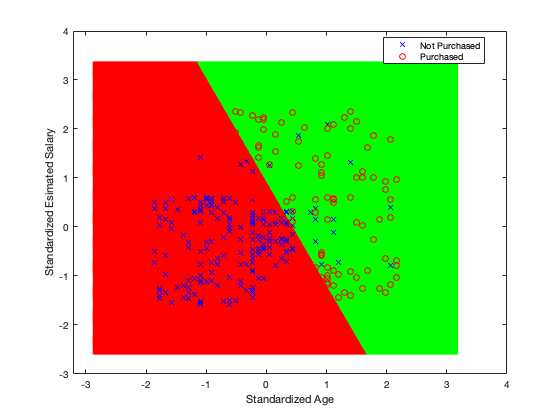

figure(1)

Age_range = min(X.Age)-1:0.01:max(X.Age)+1;
Salary_range = min(X.EstimatedSalary)-1:0.01:max(X.EstimatedSalary)+1;

[xx1, xx2] = meshgrid(Age_range,Salary_range);
XGrid = [xx1(:) xx2(:) ];
 
predictions_meshgrid = predict(da_clf,XGrid); % Change your classifier name here
gscatter(xx1(:), xx2(:), predictions_meshgrid,'rgb');
hold on

gscatter(X.Age, X.EstimatedSalary, Y, 'br','xo')
xlabel('Standardized Age')
ylabel('Standardized Esimated Salary')

## Model 2: Naive Bayes Classifier

Similarly, we fit X using a Naive Bayes classifier and calculate the cross-validation error:

nb_clf = fitcnb(X, Y);
nb_clf_cv = crossval(nb_clf);
nb_cv_error = kfoldLoss(nb_clf_cv)

nb_cv_error = 0.1031

Save the CV error of NB Classifier to the table:

cv_errors = [cv_errors; {"Naive Bayes", nb_cv_error}]; 


### Visualize Descision Boundary

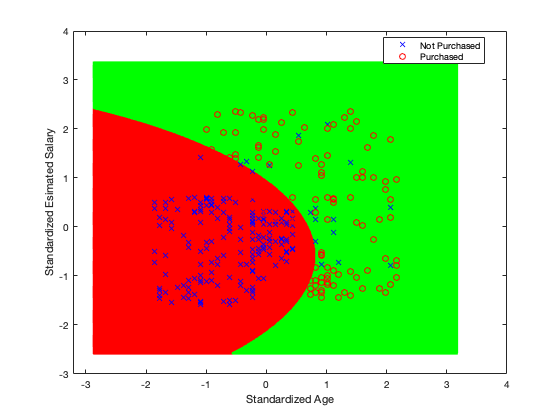

figure(2)
predictions_meshgrid = predict(nb_clf,XGrid);% Change your classifier name here
gscatter(xx1(:), xx2(:), predictions_meshgrid,'rgb');
hold on

gscatter(X.Age, X.EstimatedSalary, Y, 'br','xo')
xlabel('Standardized Age')
ylabel('Standardized Esimated Salary')

## Model 3: K-Nearest Neighbours

For KNN, use `fitcknn`, the rest of the code are pretty much the same.

NumNeighbors is a hyperparameter that you can tune.

knn_clf = fitcknn(X, Y, 'NumNeighbors',10); % Play with 'NumNeighbors'
knn_clf_cv = crossval(knn_clf);
knn_cv_error = kfoldLoss(knn_clf_cv)

knn_cv_error = 0.1000

cv_errors = [cv_errors; {"KNN", knn_cv_error}];

### Visualize Descision Boundary

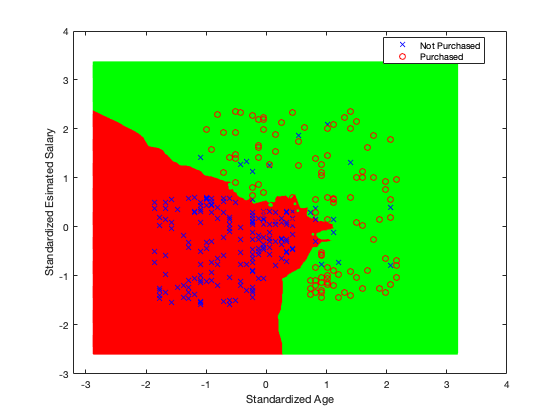

figure(3)
predictions_meshgrid = predict(knn_clf,XGrid);% Change your classifier name here
gscatter(xx1(:), xx2(:), predictions_meshgrid,'rgb');
hold on

gscatter(X.Age, X.EstimatedSalary, Y, 'br','xo')
xlabel('Standardized Age')
ylabel('Standardized Esimated Salary')

## Model 4: Support Vector Machine - Linear Kernel

svmln_clf = fitcsvm(X, Y);
svmln_clf_cv = crossval(svmln_clf);
cv_error = kfoldLoss(svmln_clf_cv)

cv_error = 0.1719

cv_errors = [cv_errors; {"SVM-Linear", cv_error}];

### Visualize Descision Boundary

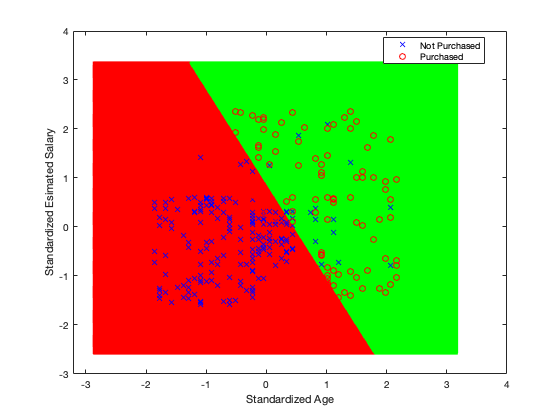

figure(4)
predictions_meshgrid = predict(svmln_clf,XGrid);% Change your classifier name here
gscatter(xx1(:), xx2(:), predictions_meshgrid,'rgb');
hold on

gscatter(X.Age, X.EstimatedSalary, Y, 'br','xo')
xlabel('Standardized Age')
ylabel('Standardized Esimated Salary')

observe that linear kernel will give you a linear (straight line) boundary.

## Model 5: Support Vector Machine - Non-linear Kernel

svmPoly_clf = fitcsvm(X, Y, 'KernelFunction','polynomial');
svmPoly_clf_cv = crossval(svmPoly_clf);
cv_error = kfoldLoss(svmPoly_clf_cv)

cv_error = 0.1031

cv_errors = [cv_errors; {"SVM-Polynomial", cv_error}];

### Visualize Descision Boundary

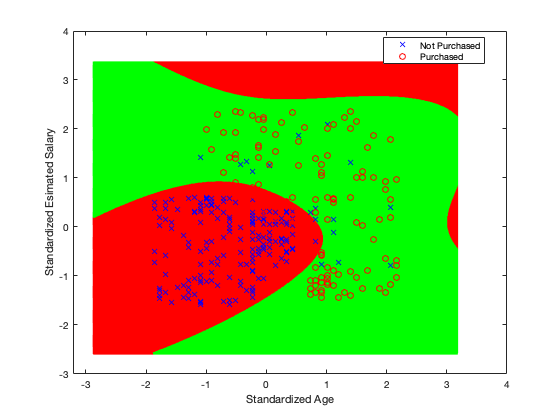

figure(5)
predictions_meshgrid = predict(svmPoly_clf,XGrid);% Change your classifier name here
gscatter(xx1(:), xx2(:), predictions_meshgrid,'rgb');
hold on

gscatter(X.Age, X.EstimatedSalary, Y, 'br','xo')
xlabel('Standardized Age')
ylabel('Standardized Esimated Salary')

Observe the red region on the top right! It does not make any sense to have a "Purchased" region there. That is definitely an overfit!

There are other non-linear kernels that you can try, such as a 

### **Gaussian Kernel:**

svmGs_clf = fitcsvm(X, Y, 'KernelFunction','gaussian');
svmGs_clf_cv = crossval(svmGs_clf);
cv_error = kfoldLoss(svmGs_clf_cv)

cv_error = 0.0875

cv_errors = [cv_errors; {"SVM-Gaussian", cv_error}];

### Visualize Descision Boundary

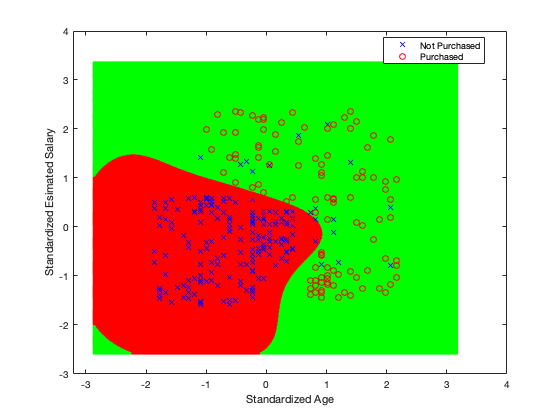

figure(6)
predictions_meshgrid = predict(svmGs_clf,XGrid);% Change your classifier name here
gscatter(xx1(:), xx2(:), predictions_meshgrid,'rgb');
hold on

gscatter(X.Age, X.EstimatedSalary, Y, 'br','xo')
xlabel('Standardized Age')
ylabel('Standardized Esimated Salary')

The decision boundary looks a little bit unphysical, with the little green bit on the left bottom, but I don't think this will cause any problem when using the model, because likely we won't get a customer of that young age.

## Model 6 (Optional): Decision Tree

tree_clf = fitctree(X, Y, 'MaxNumSplits',10); % Play with 'MaxNumSplits'
tree_clf_cv = crossval(tree_clf);
tree_cv_error = kfoldLoss(tree_clf_cv)

tree_cv_error = 0.1062

Save the CV error of NB Classifier to the table:

cv_errors = [cv_errors; {"D Tree-10", tree_cv_error}]; 


### Visualize Descision Boundary

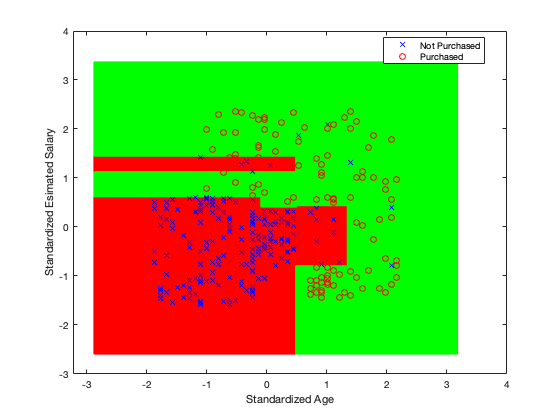

figure(6)
predictions_meshgrid = predict(tree_clf,XGrid);% Change your classifier name here
gscatter(xx1(:), xx2(:), predictions_meshgrid,'rgb');
hold on

gscatter(X.Age, X.EstimatedSalary, Y, 'br','xo')
xlabel('Standardized Age')
ylabel('Standardized Esimated Salary')

# Step 6: Fine-Tune the System

### Choose Your Final Model

Let's look at all the cross validation errors and compare:

cv_errors

cv_errors = 9×2 table
       ModelName         Error 
    ________________    _______

    "DA"                 0.1625
    "Naive Bayes"       0.10312
    "KNN"                   0.1
    "SVM-Linear"        0.17187
    "SVM-Polynomial"    0.10312
    "SVM-Gaussian"       0.0875
    "D Tree"            0.09375
    "D Tree-3"           0.0875
    "D Tree-10"         0.10625


- Looks like the SVM-Gaussian is giving us the smallest error, with a little imperfection on of the decision boundary on the left bottom, but it is not at all worrisom based on our customer range.

- The SVM-Polynomial, although having a small error, is likely overfitting the data, based on our decision boundary plot.

- KNN has the third smallest error and has a reasonable looking decision boundary.

Finally, I decide to choose SVM-Gaussian as my final ML model.

## Check Performace on Test Set

It's time to retrieve the test set and measure our best model's performance and estimate the generalization error.

Preprocess X_test the same way as we did with X_train (Here **we should use the mean and std of X_train to standardize X_test,** not the mean and std of X_test or the full data set. This is to replicate the ML model pipeline that we created above).

X_test = test_data(:, {'Age', 'EstimatedSalary'});
X_test.Age = (X_test.Age - mean(train_data.Age))/std(train_data.Age);
X_test.EstimatedSalary = (X_test.EstimatedSalary - mean(train_data.EstimatedSalary))/std(train_data.EstimatedSalary);

Then we make prediction and calculate the generalizaion error (the classification error on the test data set that the ML model has not seen).

Y_test_pred = predict(svmGs_clf, X_test); % Select your clf here
accuracy = sum((Y_test_pred == test_data.Purchased))/ height(test_data)

accuracy = 0.9125

generalization_error = 1 - accuracy

generalization_error = 0.0875

Wow the generalization error is 7.5% , even lower than that on the training data set. This is not usually the case though.

A low generalization error means that we are not overfitting the data. That's great!

# Step 7: Present Your Solution & Launch Model

This is the final step where we (pretend to) present our best model to our boss, a business man who does not know too much about ML but want to improve their car sales by hiring you, the data scientist!

You can show him a decision boundary plot of your best model against all data:

**Remember to de-normalize your data** since the boss doesn't know what standardization means!

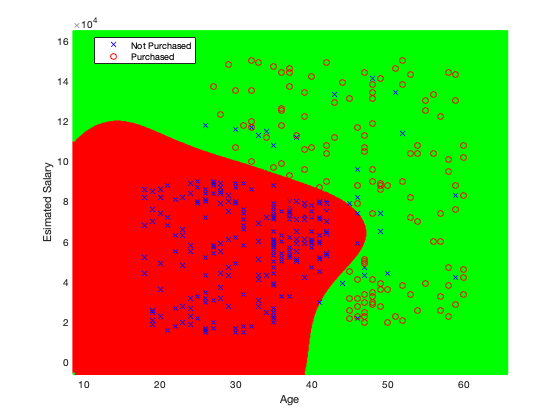

figure(7)
predictions_meshgrid = predict(svmGs_clf,XGrid);% Change best choice of classifier
% De-normalize grid data:
Age_grid = xx1(:)*std(train_data.Age) + mean(train_data.Age);
Salary_grid = xx2(:)*std(train_data.EstimatedSalary) + mean(train_data.EstimatedSalary);
% Draw decision boundary on the physical space:
gscatter(Age_grid,Salary_grid, predictions_meshgrid,'rgb');  
hold on

% Draw the actual data points
gscatter(data.Age, data.EstimatedSalary, data.Purchased, 'br','xo')
xlabel('Age')
ylabel('Esimated Salary')
axis([min(data.Age)-5, max(data.Age)+5, ...
    min(data.EstimatedSalary)-10000, max(data.EstimatedSalary)+10000])

And report that our classifier can predict 92% of the customers if they will purchase or not correctly based on their salary and age.

Also we can report that Gender is not a critical factor in the prediction and the company does not need to collect that information in the future.

# More Learning Resources

To learn more about machine learning, I would recommend you go through Andrew Ng's Coursera courses:

- Machine Learning: [https://www.coursera.org/learn/machine-learning](https://www.coursera.org/learn/machine-learning)   This course gives a detailed walk through of the most important ML algorithms. It is free, taught with MATLAB.

- Deep Learning Specializations: [https://www.coursera.org/specializations/deep-learning](https://www.coursera.org/specializations/deep-learning) This is a series of 5 courses on deep learning (neural networks). It is free to audit, and for a monthly subscription for assignments. It is taught with Python.

And to learn more about the practical side of ML, I recommend 

- this book by Aurélien Géron: [https://www.oreilly.com/library/view/hands-on-machine-learning/9781492032632/](https://www.oreilly.com/library/view/hands-on-machine-learning/9781492032632/) This is all about doing ML with Python and how to do it right.

- do as many projects as you can on kaggle and look at how other people do them. [https://www.kaggle.com/](https://www.kaggle.com/)